Wstęp:

Tematem drugich laboratoriów było ogólne wprowadzenie do modelowania układów LTI czyli liniowo niezmiennych w czasie. Wprawdzie każde zjawisko ulega zmianie jednak z fizycznego punktu widzenia niektóre z nich są znacznie bardziej rozległe. Na laboratoriach wymagane było wykorzystanie transformaty Laplace'a, przekształceń macierzowych oraz innych funkcji pomocniczych w matlabie. Najważniejszym zadaniem według mnie było porównanie odpowiedzi układu na skok jednostkowy w przypadku oscylacyjnym i tłumionym. Dzięki temu można chociażby zauważyć w jaki sposób tworzone są auta sportowe a w jaki luksusowe. Zostałem również uświadomiony, że pomimo licznych zalet tranformacje Laplace' a mają również swoje wady. Można je stosować tylko gdy układ posiada jedno wejście i jedno wyjście , warunki początkowe są zerowe i równania opisujące układ są liniowe.  

W przykładzie pierwszym pracowałem na zmiennych symbolicznych. Dlatego też potrzebne było polecenie syms, które utworzy mi takie parametry. Następnie użyłem funckji heaviside oraz laplace, które tworzyły odpowiednie równania. Stanowiło to niezbędną podkładkę pod zadanie 1, gdzie należało dokonać odpowiednich przekształceń w oparciu na przykład.

Przykład 1:

syms t s
syms a positive
f = heaviside(t-a)

$$f = \mathrm{heaviside}\left(t-a\right)$$

Fs = laplace(f, t, s)

$$Fs = \frac{{\mathrm{e}}^{-a\,s}}{s}$$

Poniższe zadanie polegało na wytworzeniu przestrzeni liczbowej przez funkcje laplace oraz heaviside, gdzie pod parametr a wstawiłem 1. Następnie za pomocą funkcji fplot gdzie podawałem funkcję i zakres x tej funkcji(dodałem również funkcję ylim, która zdeterminowała mi przedział y - ków) tworzyłem wykresy odpowiadające konkretnym przekształceniom

Zadanie 1:

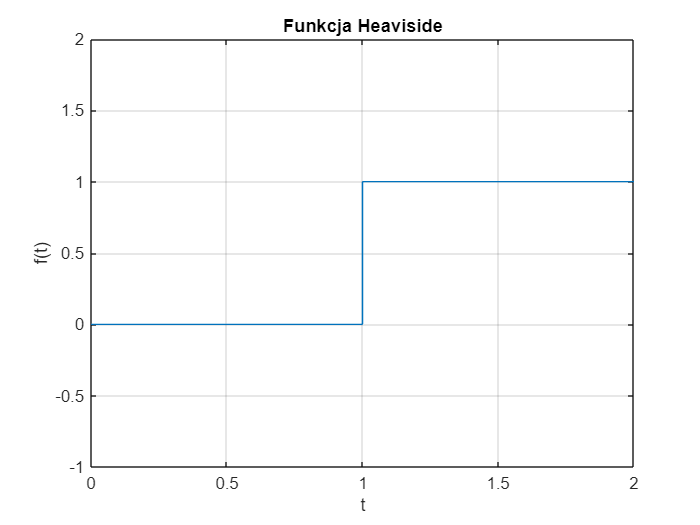

    
syms t s 
    a = 1;
    f = heaviside(t - a);
    
    Fs = laplace(f, t, s);    
    figure; 
    fplot(f, [0, 2]); % tutaj stworzyłem poniższy wykres funckji
    ylim([-1,2]) % określiłem przedział y ( chciałem aby moment "wygięcia" został uchwycony na wykresie)
    title(['Funkcja Heaviside']); % nadałem tytuł tabelce dla czytelności
    xlabel('t');
    ylabel('f(t)'); % opisałem oś x oraz y 
    grid on; % włączam siatkę na wykresie

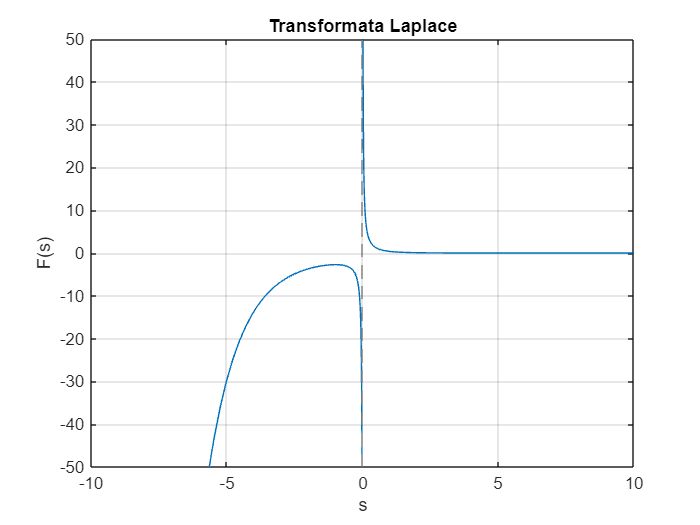

    
    figure; % otwieram kolejne okno dla kolejnego wykresu i dokonuję podobnych przekształceń co powyżej, tyle że dla funkcji laplace
    fplot(Fs, [-10, 10]); 
    ylim([-50, 50]) 
    title(['Transformata Laplace']);
    xlabel('s');
    ylabel('F(s)');
    grid on;

Przykład drugi pokazuje w jaki sposób można opisać dowolny problem LTI. W zadaniu mamy do opisania model zawieszenia samochodowego składający się z masy, tłumika oraz sprężyny. Całość sprowadza się do równania M x"  + alfa * x'  + cx = F. Następnie poddając równanie transformacie Laplace'a  wyliczamy transmitancję czyli(zakładając, że F(s) jest wejściem, a X(s) wyjściem) G(s) = X(s) / F(s). Do symulacji użyłem konkretnych warunków początkowych. W tym celu określam wektory licznika i mianownika. Następnie metodami step(odpowiedzi skokowej), impulse(odpowiedzi impulsowej) oraz tf(tworzę równanie opisujące obiekt) tworzę do niej odpowiednie wykresy.

Przykład 2:

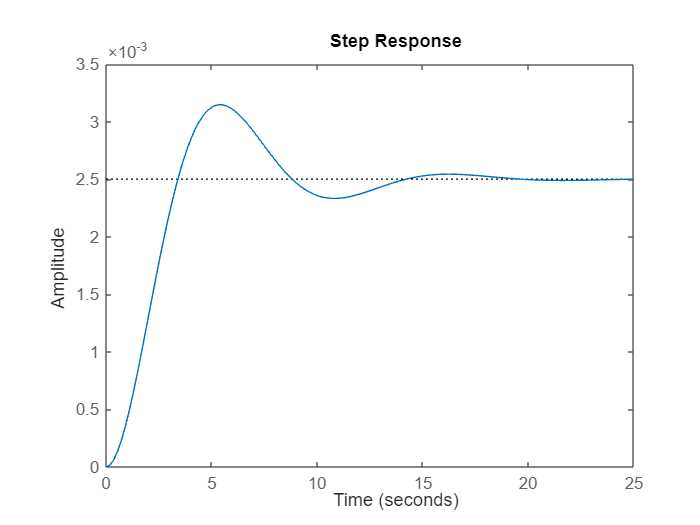

licz = [0 0 1];
mian = [1000 500 400];

step(licz,mian) % tworzy wykres dla odpowiedzi skokowej

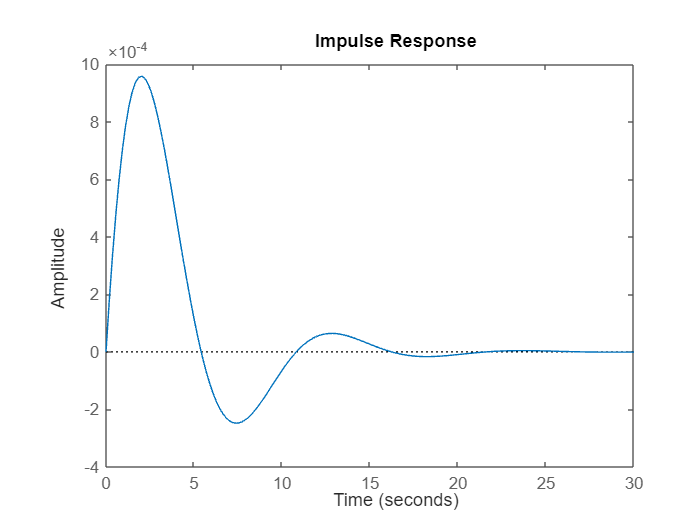

impulse(licz,mian) % tworzy wykres dla odpowiedzi impulsowej

obiekt = tf(licz,mian) % tworzy ułamek na bazie zadanych licznika i mianownika 

obiekt =
 
            1
  ----------------------
  1000 s^2 + 500 s + 400
 
Continuous-time transfer function.
Model Properties


get(obiekt) % wyświetla pola struktury obiekt

       Numerator: {[0 0 1]}
     Denominator: {[1000 500 400]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



step(obiekt); % szybsza metoda kiedy mamy już przygotowaną całą funkcję

impulse(obiekt);

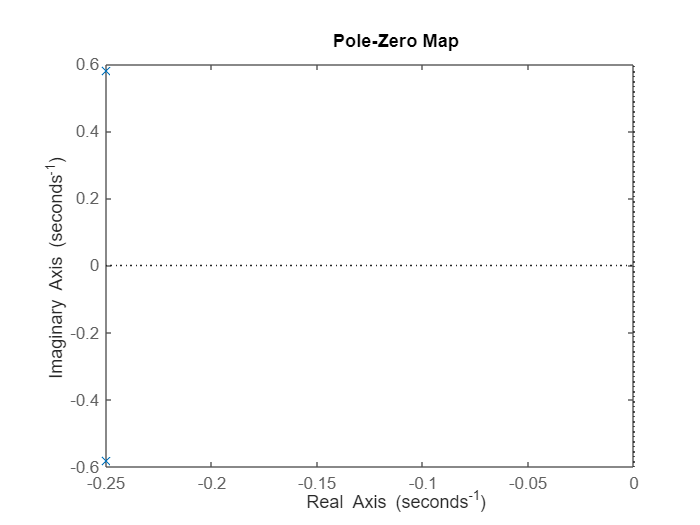

[z, p, k] = tf2zp(licz, mian); %przypisywanie zmiennym zer biegunów oraz wzmocnienia
pzmap(p,z) % mapowanie zer i jedynek na płaszczyznę zespoloną

%pzmap(licz,mian);
%pzmap(obiekt);


Zadanie drugie było najciekawszym zadaniem z całego zestawu. Początkowo stwierdziłem czy bieguny są rzeczywiste oraz na ich podstawie oceniłem stabilność układu. Następnie obliczyłem zera, bieguny oraz wzmocnienie układu przedstawiając transmitancję w postaci sfaktoryzowanej oraz standardowej. Na koniec dobrałem odpowiednio parametry takie jak współczynnik tłumienia czy stałą tłumika (masą M czy też stałą sprężyny c ciężko by się manipulowało) aby zobaczyć odpowiedzi oscylacyjne i tłumione .  Dzięki tym ruchom z łatwością można stwierdzić, że w samochodach luksusowych występuje większe dbanie o komfort niż w samochodach sportowych. Tym samym współczynnik tłumienia jest tam mniejszy, a efekty widać na załączonym poniżej wykresie.

Zadanie 2:

licz  = [0 0 1];
mian = [1000 500 400];
syms s;
M = 1000;
alfa = 500;
c = 400; % dobieram parametry zgodnie z treścią zadania

wspTlum = [0.5 1]; % współczynniki tłumienia określiłem zgodnie z zaleceniami prowadzącego

% odp na zadanie 1 a) bieguny nie są rzeczywiste
% odp na zadanie 1 b) układ jest stabilny gdyż wpółczynniki stojące przy
% części rzeczywistej pierwiastków są ujemne,
[z,p,k] = tf2zp(licz,mian);
faktoryzacja = k * prod(s - z) / prod(s - p);
standard = @(c,alfa,M)  (1/c) ./ ((M/c)*s^2 + (alfa./c) * s + 1); % przedstawiam transmitancję w postaci sfaktoryzowanej oraz standardowej

%nowa alfa
alfa1 = wspTlum(1,1) * 2 * sqrt(M * c);
alfa2 = wspTlum(1,2) * 2 * sqrt(M * c);

%transmitancje
transmitancja1 = standard(c, alfa1, M); % układ oscylacyjny
transmitancja2 = standard(c, alfa2, M); % układ tłumiony
display(transmitancja1); % wyświetlam równanie transmitancji w czytelnej formie przez funckję display

$$transmitancja1 = \frac{1}{400\,\left(\frac{5\,s^{2}}{2}+\frac{\sqrt{2}\,\sqrt{5}\,s}{2}+1\right)}$$

display(transmitancja2);

$$transmitancja2 = \frac{1}{400\,\left(\frac{5\,s^{2}}{2}+\sqrt{10}\,s+1\right)}$$


licz12 = [0 0 1];
mian1 = [M, alfa1, c]; 
mian2 = [M, alfa2, c]; % tworzę ułamki z nowymi alfami po przekształceniach 
oscylacje = tf(licz12, mian1)

oscylacje =
 
             1
  ------------------------
  1000 s^2 + 632.5 s + 400
 
Continuous-time transfer function.
Model Properties


tlumienie = tf(licz12, mian2)

tlumienie =
 
             1
  -----------------------
  1000 s^2 + 1265 s + 400
 
Continuous-time transfer function.
Model Properties


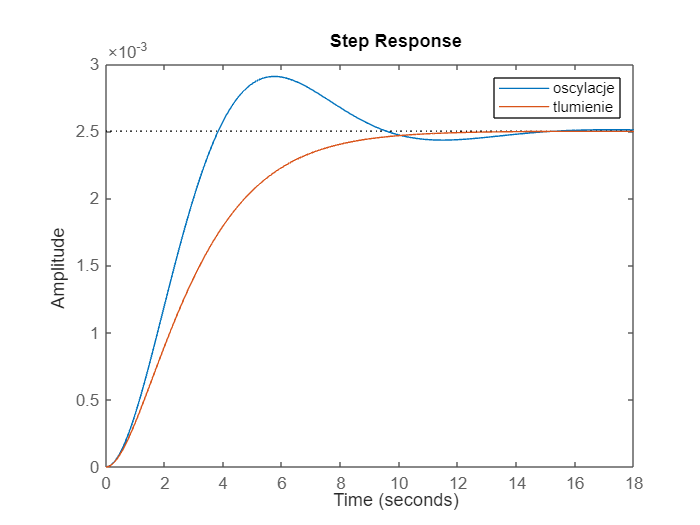

step(oscylacje, tlumienie) % wyświetlam wykres razem ze stosowną legendą do odpowiedz skokowej
legend('oscylacje', 'tlumienie')

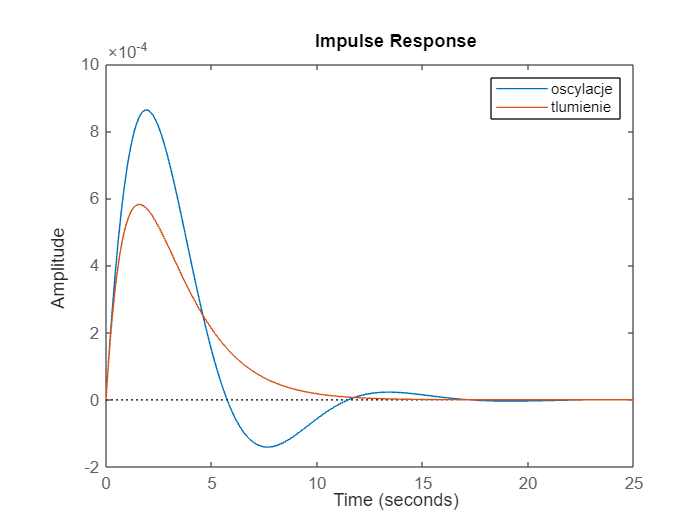

impulse(oscylacje,tlumienie) % wyświetlam wykres razem ze stosowną legendą do odpowiedz impulsowej
legend('oscylacje', 'tlumienie')

Głównym celem przykładu 3 było pokazanie w jaki sposób poradzić sobie z problemem wyświetlenia transmitancji przez funckję zpk. W tym celu trzeba otrzymać licznik i mianownik w postaci wielomianowej stosując funkcję zp2tf, a następnie pristsys-sem lub zpk wyświetlić transmitancję.

Przykład 3:

[licz,mian] = zp2tf(-1/3,[0 -1 -3],3);
printsys(licz,mian)

 
num/den = 
 
        3 s + 1
   -----------------
   s^3 + 4 s^2 + 3 s


Zadanie nr 3 wymagało ode mnie wyświetlenia transmitancji dla funkcji o zadanych parametrach za pomocą funkcji zpk.  

Zadanie 3:

obiekt = zpk(-1/4,[-5 -0.1 0], 2)

obiekt =
 
    2 (s+0.25)
  ---------------
  s (s+5) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


Kolejny przykład zrealizowałem równolegle z rozwiązaniem zadania nr 4. W tym zadaniu chodzi o modelowanie układów LTI w przestrzeni stanów. Opisujemy je za pomocą macierzy A, B, C, D, które określają zależności między stanami układu, jego wejściem (sygnałem sterującym) i wyjściem. Następnie, przy użyciu MATLAB-a, definiujemy te macierze i tworzymy obiekt układu za pomocą funkcji ss. Dzięki temu możemy analizować odpowiedzi układu, takie jak odpowiedź skokowa (step) czy impulsowa (impulse). Można też przekształcać transmitancje na reprezentację w przestrzeni stanów za pomocą funkcji tf2ss lub zp2ss   , oraz obliczać wzmocnienie układu w stanie ustalonym przy użyciu dcgain.

Przykład 4 / Zadanie 4:

c = 400;
F = 1000;
alfa = 500;
M = 1000;
A = [0, 1;-c/M -alfa/M];
B = [0 ; 1/M];
C = [1 0];
D = 0;
obiekt = ss(A,B,C,D) % tworzę obiekt z macierzy

obiekt =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.4  -0.5
 
  B = 
          u1
   x1      0
   x2  0.001
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


step(obiekt) % tworzę wykres skokowy zmiennej obiekt

impulse(obiekt) %tworzę wykres impulowy zmiennej obiekt

k = 4;
z = -1/4;
p = [-5 -0.1 0];
[licz,mian] = zp2tf(-1/4,[0 -0.1 -5],4);
[A1,B1,C1,D1] = zp2ss(z,p,k)

A =          0         0         0
    0.2500   -5.1000   -0.7071
         0    0.7071         0


B =      1
     1
     0


C =          0         0    5.6569


D = 0

[A2,B2,C2,D2] = tf2ss(licz,mian) % muszę nadać zmiennym inne nazwy nie A B C D ponieważ będę je modyfikować

A =    -5.1000   -0.5000         0
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =      0     4     1


D = 0

k = dcgain(A,B,C,D) %liczę wzmocnienie w stanie ustalonym

k = 0.0025

% z powyższej analizy wynika, że macierze nie są takie same. 
% teraz przechodzę do zadania 4 gdzie wystarczy już podstawić tylko
% poprawne dane
M = 1000;
F = 1000;
alfa = 500;
c = 400;


A_ZAW = [0 1; -c/M -alfa/M];
B_ZAW = [0; 1/M];
C_ZAW = [1 0];
D_ZAW = 0; % definiuję zmienne A, B , C, D dla zawieszenia


licz_ZAW = [0 0 1];
mian_ZAW = [M alfa c]; % definiuję licznik i mianownik transmitancji
[z_ZAW, p_ZAW, k_ZAW] = tf2zp(licz_ZAW, mian_ZAW); % wyliczam zera bieguny oraz wzmocnienie transmitancji
[A_ZAW1,B_ZAW1,C_ZAW1,D_ZAW1] = zp2ss(z_ZAW, p_ZAW, k_ZAW)

A_ZAW1 =    -0.5000   -0.6325
    0.6325         0


B_ZAW1 =      1
     0


C_ZAW1 =          0    0.0016


D_ZAW1 = 0

[A_ZAW2,B_ZAW2,C_ZAW2,D_ZAW2] = tf2ss(licz_ZAW, mian_ZAW)

A_ZAW2 =    -0.5000   -0.4000
    1.0000         0


B_ZAW2 =      1
     0


C_ZAW2 = 1.0e-03 *

         0    1.0000


D_ZAW2 = 0

Przykład 5 również realizowałem równolegle z zadaniem 5. Ideą było połączenie dwóch obiektów w jeden, tym samym nadając mu transmitancję zastępczą. W ten sposób za pomocą funkcji series można łączyć obiekty szeregowo, za pomocą parallel równolegle oraz za pomocą feedback przez sprzężenie zwrotne. Zadanie 5 wymagało ode mnie połączenia obiektów za pomocą tych gd

Przykład 5 / Zadanie 5:

sys1 = tf([0 1 1], [1 5 1]);
sys2 = tf([0 0 0 1], [1 1 -2 1]);
%polaczenie_szeregowe = sys1 + sys2 - pierwsza metoda na wykonanie operacji
%połączenia szeregowego dwóch obiektów
polaczenie_szeregowe = series(sys1,sys2) % druga metoda

polaczenie_szeregowe =
 
                  s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


%polaczenie_rownolegle = parallel(sys1,sys2) - pierwsza metoda na wykonanie operacji
%połączenia równoległego dwóch obiektów
polaczenie_rownolegle = parallel(sys1,sys2) % - druga metoda 

polaczenie_rownolegle =
 
          s^4 + 2 s^3 + 4 s + 2
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


sprzerzenie_zwrotne_ujemne = feedback(sys1, sys2)

sprzerzenie_zwrotne_ujemne =
 
        s^4 + 2 s^3 - s^2 - s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 4 s + 2
 
Continuous-time transfer function.
Model Properties


sprzerzenie_zwrotne_dodatnie = feedback(sys1,sys2,+1)

sprzerzenie_zwrotne_dodatnie =
 
      s^4 + 2 s^3 - s^2 - s + 1
  ---------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties
